# Evaluate the elevation map sensor model on the campus of the University of Freiburg

Read the point cloud data.

% Read the map point cloud.
pcMap = removeInvalidPoints(pcread('pcd/data/campus_freiburg.pcd'));
pcMap = pcdownsample(pcMap, 'gridAverage', 0.005);
pcMap = select(pcMap, findPointsInROI(pcMap, [-15, 95; -80, 0; -Inf, +Inf]));

% Read the sensor point cloud.
pcSensor = removeInvalidPoints(pcread('pcd/data/bonirob_campus.pcd'));
pcSensor = pcdownsample(pcSensor, 'gridAverage', 0.005);
tfinit = [quat2rotm([1, -0.009, -0.000, -0.027]), [55.725; -42.839; 0.780]; 0, 0, 0, 1];
pcSensor = pctransform(pcSensor, ht2affine3d(tfinit));

Register the map and the sensor point cloud.

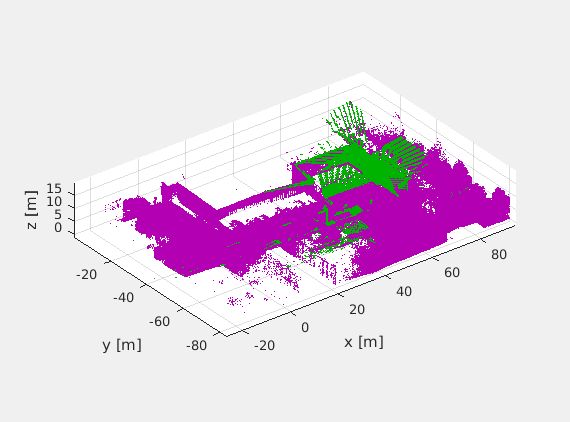

% Register the point clouds using ICP.
tfreg = pcregrigid(pcSensor, pcMap, 'Tolerance', [0.001, 0.001]);
pcSensorReg = pctransform(pcSensor, tfreg);
pcshowpair(pcMap, pcSensorReg); labelaxes('m')

Create an elevation map from the map point cloud.

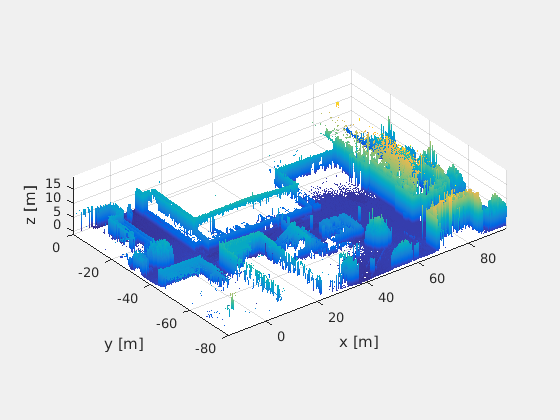

% Create the elevation map and fill the gaps in the map.
em = fillnan(elevationmap(pcMap, 0.05), [5,5]);
em.plot; labelaxes('m'); grid

Shift the scan and for each offset compute how well the scan matches the map.

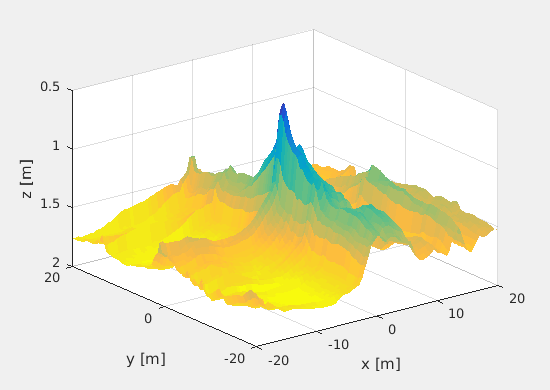

% Define the offsets in x- and y-direction.
x = -20 : 0.5 : +20;
y = -20 : 0.5 : +20;
nx = numel(x);
ny = numel(y);

% Initialize the matrix that stores the mean z-difference.
d = NaN(nx, ny);

% Loop over all offsets.
parfor ix = 1 : nx
    for iy = 1 : ny
        % Shift the scan horizontally.
        p = pcSensor.Location + repmat([x(ix),y(iy),0], pcSensor.Count, 1);
               
        % Compute the mean difference in z for all points of the scan.
        % Allow only positive values, as negative differences mean the scan
        % hit an object and the corresponding point is correct.
        dz = em.diff(p);
        dz(isnan(dz)) = p(isnan(dz),3);
        d(ix,iy) = mean(constrain(dz, [0,+Inf]));
    end
end

% Plot the mean of the z-distance for all offsets.
surf(x, y, d', 'EdgeColor', 'none'); set(gca, 'Zdir', 'reverse'); labelaxes('m');